# Linearize Differential Equations

**Objective:** Linearize the nonlinear diffferential equations and compare the linearized model simulation to the original nonlinear model response

## Exercise 1 - Automobile

viewSolutionAutomobile(false)

Linearize the momentum balance for the velocityof an automobile at steady state conditions when the das pedal is maintained at 40%.


$$m\frac{dv(t)}{dt} = F_p u(t) - \frac{1}{2} \rho \, A \, C_d v(t)^2$$


with $u(t)$ as gas pedal position ($\text{% pedal$), $v(t)$ as velocity ($\frac{\text{m}}{\text{s}}$), $m$ as the mass of the vehicle ($\text{500 kg}$) plus the mass of the passengers and cargo ($\text{200 kg}$), $C_d$ as the drag coefficient (0.24), $\rho$ as the air density ($\text{1.225} \frac{\text{kg}}{\text{m}^3}$), $A$ as the vehicle cross-sectional area ($\text{5 m}^2$), and $F_p$ as the thrust parameter ($\text{30} \frac{\text{N}}{\text{\% pedal}}$). Simulate a step change in the gas pedal position, comparing the nonlinear response to the linear response. Comment on the accuracy of the linearized model.

### Take the partial derivatives of the system

MATLAB can calculate derivatives symbolically or numerically. Take the partial derivatives with respect to $u$ and $v$. With the momentum balance as $f(u, v)$, assign $\alpha=\frac{\delta f}{\delta u}$ and 

#### Symbolic Derivation

syms v u Fp rho Cd A m
momentum_balance = Fp * u / m - rho * A * Cd * v^2 / (2 * m)

$$momentum\_balance = \frac{\mathrm{Fp}\,u}{m}-\frac{A\,\mathrm{Cd}\,\rho \,v^{2}}{2\,m}$$

dmdu = diff(momentum_balance, u)

$$dmdu = \frac{\mathrm{Fp}}{m}$$

dmdv = diff(momentum_balance, v)

$$dmdv = -\frac{A\,\mathrm{Cd}\,\rho \,v}{m}$$

Substitute values into symbolic solutions. The substitutions for $v$ and $u$ are the steady state values. The steady state pedal position $u_{ss}=40$. The steady state velocity is determined by setting the time derivative to zero, plugging in other steady state conditions, and solving for $v_{ss}$.


$$m\frac{dv(t)}{dt} = F_p u(t) - \frac{1}{2} \rho \, A \, C_d v(t)^2$$



$$0 = F_p u_{ss} - \frac{1}{2} \rho \, A \, C_d v_{ss}^2$$



$$v_{ss} = \sqrt{\frac{2 \, F_p u_{ss}}{\rho \, A \, C_d}}$$



$$v_{ss} = \sqrt{\frac{2 \times 30 \frac{N}{\%} \times 40 \%}{1.225 \frac{kg}{m^3} \times 5 m^2 \times 0.24}} = 40.406 \frac{m}{s}$$


Below, `subs` accepts the symbolic expression to be subtituted into, one or more symbolic variables, and their corresponding values. `double` then converts the solution to a numeric decimal form.

vss = sqrt((2*30*40)/(1.225 * 5 * 0.24))

vss = 40.4061

alpha = double(subs(dmdu, [v u Fp rho Cd A m], [vss 40 30 1.225 0.24 5 700]))

alpha = 0.0429

beta = double(subs(dmdv, [v u Fp rho Cd A m], [vss 40 30 1.225 0.24 5 700]))

beta = -0.0849

### Nonlinear Model

dvdt_nonlinear = @(t, v, u, load)(30 * u - 0.5 * 1.225 * 0.24 * 5 * v^2)/(500+load);

### Create Linearized model

Create a similar function that creates a linearized model for use with ode45. Use the below function as an example.


$$\frac{dv(t)}{dt} = \alpha \left(u(t) - 40\right) + \beta \left(v(t)-v_{ss}\right)$$


dvdt_linear = @(t, v, u, load)alpha * (u - 40) + beta * (v - vss);

### Compare Nonlinear and Linear Model

Create storage arrays

time_space = linspace(0, 60, 61);
u = zeros(1, 61);
u(11:end) = 40;
v_nonlinear = zeros(1, 61);
v_linear = zeros(1, 61);

Simulate with ode45

load = 200;
for i = 1:length(time_space)-1
    [~, y] = ode45(@(t, y)dvdt_nonlinear(t, y, u(i), load), [time_space(i) time_space(i+1)], v_nonlinear(i));
    v_nonlinear(i+1) = y(end);
    [~, y] = ode45(@(t, y)dvdt_linear(t, y, u(i), load), [time_space(i) time_space(i+1)], v_linear(i));
    v_linear(i+1) = y(end);
end

Graph

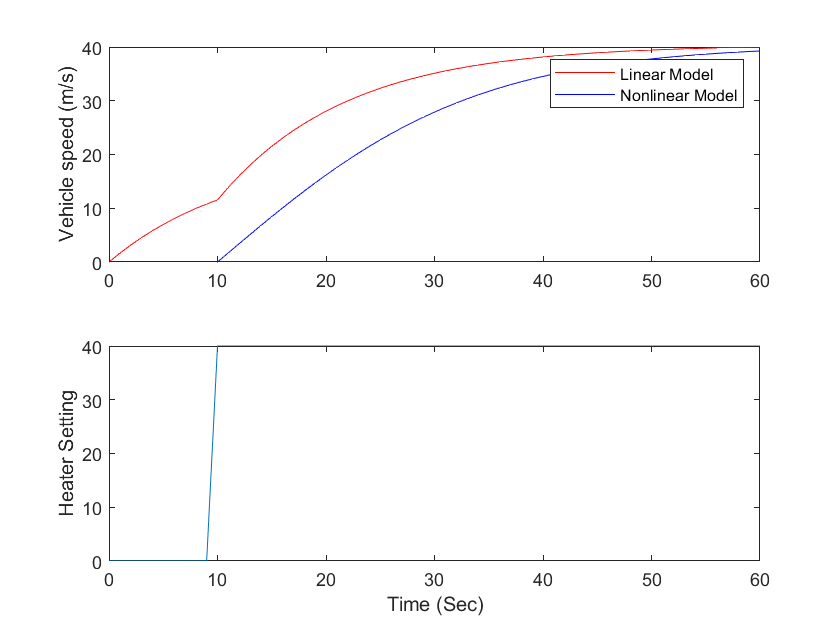

figure(1)
subplot(2,1,1)
plot(time_space, v_linear, 'r-', 'DisplayName','Linear Model')
hold on;
plot(time_space, v_nonlinear, 'b-', 'DisplayName','Nonlinear Model')
hold off;
ylabel('Vehicle speed (m/s)')
legend()
subplot(2,1,2)
plot(time_space, u)
ylabel('Heater Setting')
xlabel('Time (Sec)')

## Exercise 2 - Thermocouple

function viewSolutionThermocouple(false)

Linearize an energy balance that describes the temperature of a thermocouple bead $T_t$ given a change in the surrounding gas temperature $T_g$. Include the flame temperature $T_f$ as a variable in the linearization. Simulate a cyclical gas temperature change and a step change in flame temperature in both the linear and nonlinear versions of the model.

Some advanced combustion systems operate in a pulsed mode where an acoustic wave resonates in the combustor in order to enhance heat and mass transfer. The frequency of the wave is approximately 100Hz (cycles/sec). As a result, the temperature at any given spatial location in the combustor fluctuates with time. The fluctuations can be approximated as a sine wave with an amplitude of $75^\circ \text{C}$ for the system of interest. The objective is to measure the fluctuating temperature at a given point in the reactor with use of a thermocouple.

Heat is transferred to the thermocouple by convection and radiation. Heat transfer by radiation is approximated by $q = A \epsilon \sigma (T_f^4-T_t^4)$ where $A$ is the surface area, $\epsilon$ is the emissivity, and $\sigma$ is the Stefan-Boltzmann constant ($\frac{\text{W}}{\text{m}^2\text{K}^4}$). The thermocouple bead is approximated as a sphere (e.g. ignore conduction along connecting wires).

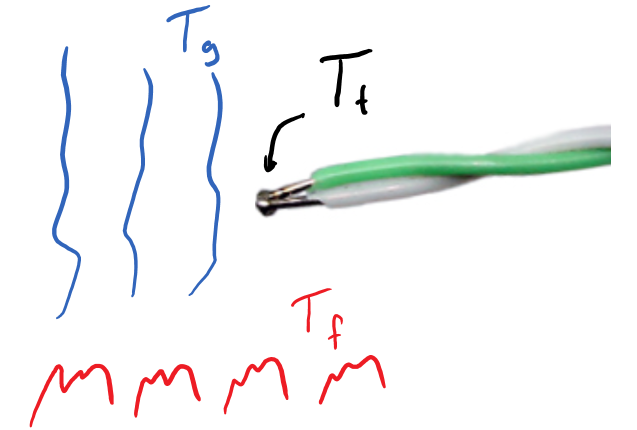

Use the following values with subscript *t* as the thermocouple, subscript *f* as the flame, *ss* indicating steady-state, $h$ as the heat transfer coefficient, $c_p$ as the heat capacity, $\rho$ as the density, and $d_t$ as the diameter of the thermocouple bead.


$$h=2800 \, \frac{W}{m^2 \, K} \quad \rho_{t} = 20 \, g/cm^3 \quad \sigma = 5.67e-8 \, \frac{W}{m^2\,K^4}$$



$$\epsilon=0.8 \quad T_{t,ss} = 1500 \, K \quad T_{f} = 1500 \, K$$



$$c_{p,t} = 0.4 \frac{J}{g\,K} \quad d_t = 0.01 \, cm$$


A starting script is available below. Add the linearized balance equation in addition to the nonlinear balance equation that is already implemented in the function at the bottom of this script. Simulate both for the cycling gas temperature and discuss whether the linearized model is a suitable approximation of the nonlinear model. What changes could be made to the thermocouple to improve the ability to measure gas temperature?

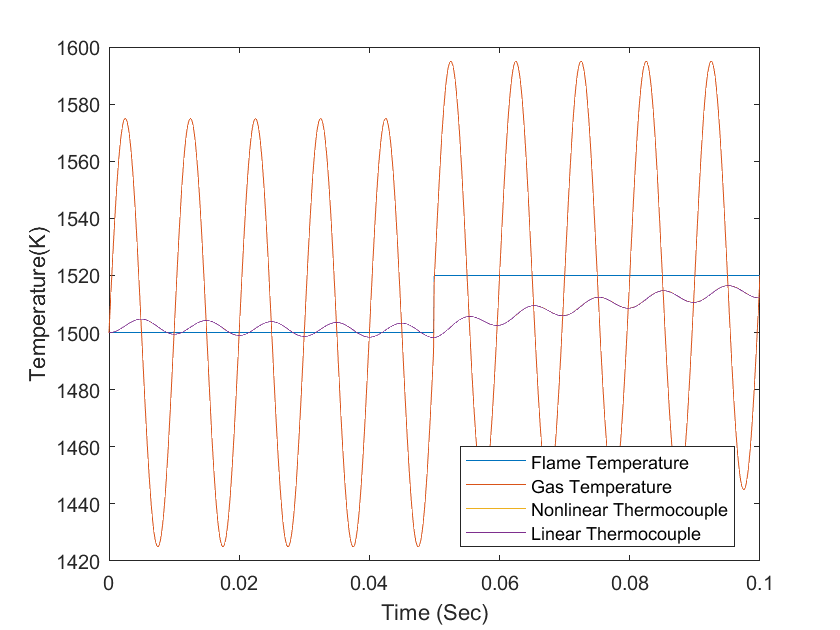

Tf0 = 1500;  % Initial flame temperature (K)
y0 = [Tf0; Tf0];  % Initial Thermocouple temperature
t_ = linspace(0, 0.1, 1e3);  % Time Interval
Tf = ones(1, 1e3) * Tf0;  % Flame Temperature
Tf(500:end) = 1520;
Tg = Tf + (150.0/2.0) * sin(2.0 * pi * 100.0 * t_);  % Gas temperature cycles (K)

% Results storage
Tt = ones(1, length(t_)) .* Tf;
Tlin = ones(1, length(t_)) .* Tf;

% Simulate with ode45
for i = 1:1e3-1
    ts = [t_(i) t_(i+1)];
    [~, y] = ode45(@(t,y)thermocouple(t,y,Tg(i),Tf(i)), ts, y0);
    y0 = y(end,:);
    Tt(i+1) = y0(1);
    Tlin(i+1) = y0(2);
end

plot(t_, Tf, 'DisplayName','Flame Temperature')
hold on;
plot(t_, Tg, 'DisplayName','Gas Temperature')
hold on;
plot(t_, Tt, 'DisplayName','Nonlinear Thermocouple')
hold on;
plot(t_, Tlin, 'DisplayName','Linear Thermocouple')
hold off;
xlabel('Time (Sec)')
ylabel('Temperature(K)')
legend('Location',"best")

function dT = thermocouple(~, T, Tg, Tf)
    % unpack T
    Tt = T(1);
    Tlin = T(2);
    
    % Parameters
    h = 2800.0;            % W/m^2-K
    rho = 20.0;            % gm/cm^3
    sigma = 5.67e-8;       % W/m^2-K^4
    eps = 0.8;             %
    Cp = 0.4;              % J/gm-K    
    d = 0.01;              % cm
    r = d / 2.0;           % radius
    A = 4.0 * pi * (r/100.0)^2; % sphere area (m^2)
    V = 4.0/3.0 * pi * r^3;     % sphere volume (cm^3)    
    
    % Accumulation = in - out
    % Accumulation = m * Cp * dT/dt = rho * V * Cp * dT/dt
    % inlet - outlet from 2 heat transfer pathways
    % q(convection) = h * A * (Tg-Tt)
    % q(radiation) = A * esp * sigma * (Tf^4 - Tt^4)
    q_conv = h * A * (Tg-Tt);
    q_rad = A * eps * sigma * (Tf^4 - Tt^4);
    dTdt = (q_conv + q_rad) / (rho * V * Cp);
    T0 = 1500;
    denominator = rho * V * Cp;
    alpha = (-h * A - 4 * T0^3 * A * eps * sigma) / denominator;
    beta = (h*A)/denominator;
    gamma = 4 * T0^3 * A * eps * sigma/denominator;
    dTlin_dt = alpha * (Tlin - T0) + beta * (Tg-T0) + gamma * (Tf-T0); % add linearized equation
    dT = [dTdt; dTlin_dt];
end


Display Solutions

function viewSolutionAutomobile(view)
if view
	 "dvdt_linear = @(t, v, u, load)alpha * (u - 40) + beta * (v - vss);")
end
end

function viewSolutionThermocouple(view)
if view
	disp("function dT = thermocouple(~, T, Tg, Tf)" + newline + ...
	     "    % unpack T" + newline + ...
	     "    Tt = T(1);" + newline + ...
	     "    Tlin = T(2);" + newline + ...
	     "    " + newline + ...
	     "    % Parameters" + newline + ...
	     "    h = 2800.0;            % W/m^2-K" + newline + ...
	     "    rho = 20.0;            % gm/cm^3" + newline + ...
	     "    sigma = 5.67e-8;       % W/m^2-K^4" + newline + ...
	     "    eps = 0.8;             %" + newline + ...
	     "    Cp = 0.4;              % J/gm-K    " + newline + ...
	     "    d = 0.01;              % cm" + newline + ...
	     "    r = d / 2.0;           % radius" + newline + ...
	     "    A = 4.0 * pi * (r/100.0)^2; % sphere area (m^2)" + newline + ...
	     "    V = 4.0/3.0 * pi * r^3;     % sphere volume (cm^3)    " + newline + ...
	     "    " + newline + ...
	     "    % Accumulation = in - out" + newline + ...
	     "    % Accumulation = m * Cp * dT/dt = rho * V * Cp * dT/dt" + newline + ...
	     "    % inlet - outlet from 2 heat transfer pathways" + newline + ...
	     "    % q(convection) = h * A * (Tg-Tt)" + newline + ...
	     "    % q(radiation) = A * esp * sigma * (Tf^4 - Tt^4)" + newline + ...
	     "    q_conv = h * A * (Tg-Tt);" + newline + ...
	     "    q_rad = A * eps * sigma * (Tf^4 - Tt^4);" + newline + ...
	     "    dTdt = (q_conv + q_rad) / (rho * V * Cp);" + newline + ...
	     "    T0 = 1500;" + newline + ...
	     "    denominator = rho * V * Cp;" + newline + ...
	     "    alpha = (-h * A - 4 * T0^3 * A * eps * sigma) / denominator;" + newline + ...
	     "    beta = (h*A)/denominator;" + newline + ...
	     "    gamma = 4 * T0^3 * A * eps * sigma/denominator;" + newline + ...
	     "    dTlin_dt = alpha * (Tlin - T0) + beta * (Tg-T0) + gamma * (Tf-T0); % add linearized equation" + newline + ...
	     "    dT = [dTdt; dTlin_dt];" + newline + ...
	 "end")
end
end